## Solve a mass-spring-damper system

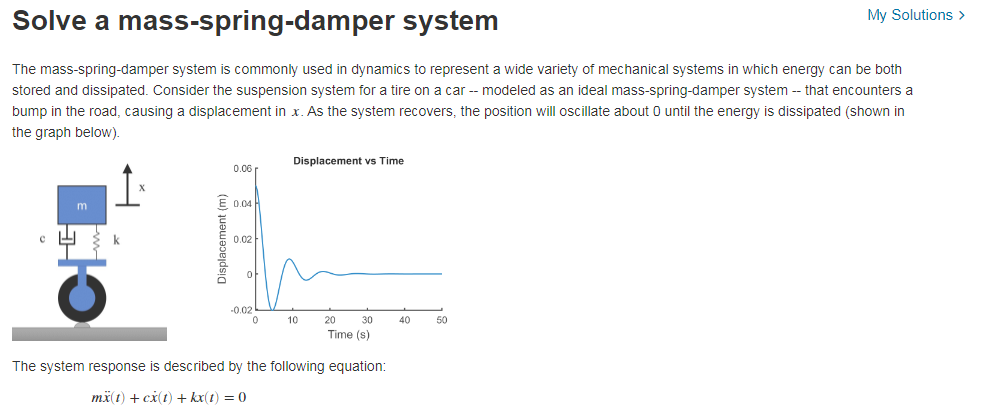

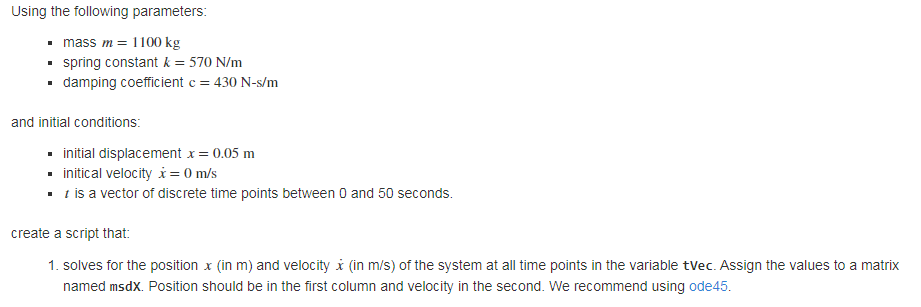

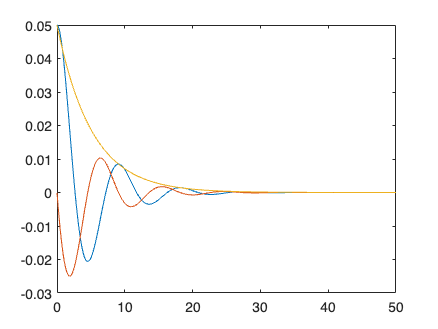

tVec = 0:0.1:50;  % Discrete time interval, s

% Model parameters (can be moved to where needed in your script)
m = 1100;         % kg
k = 570;          % N/m
c = 430;          % N-s/m

% Write your solution below
x=[0.05;0];
posVelx=@(t,x) [x(2);-(c*x(2)+k*x(1))/m];
[t msdX]=ode45(posVelx,tVec,x);
plot(t,msdX)

%Comentrios
%x'=v y x''=v'=-(c/m)v-(k/m)x
%xv=[x;v]
%(xv)'=M*xv
M=[0 1; -(k/m) -(c/m)];
lambda=eig(M);
ct=real(lambda);
hold on;
plot(t,x(1)*exp(ct(1)*t))


w=imag(lambda(1));%frecuencia angular
f=w/(2*pi)%frecuencia en periodos por segundo

f = 0.1103

periodo=1/f

periodo = 9.0692


%La ecuación característica de una ODE de 2ndo orden
%lambda^2+(c/m)*lambda+k/m=0;